## Diodos

### 3.1 Curva Característica

    Considerando o circuito abaixo, para descrevermos a curva característica a $V_D \times I_D$ precisamos medir a tensão de entrada $V_{in}$ e $V_D$ para então calcularmos a corrente no resistor pela fórmula:


$$I_D = \frac{(V_{in} - V_D)}{R}
$$


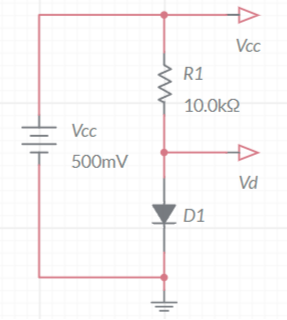

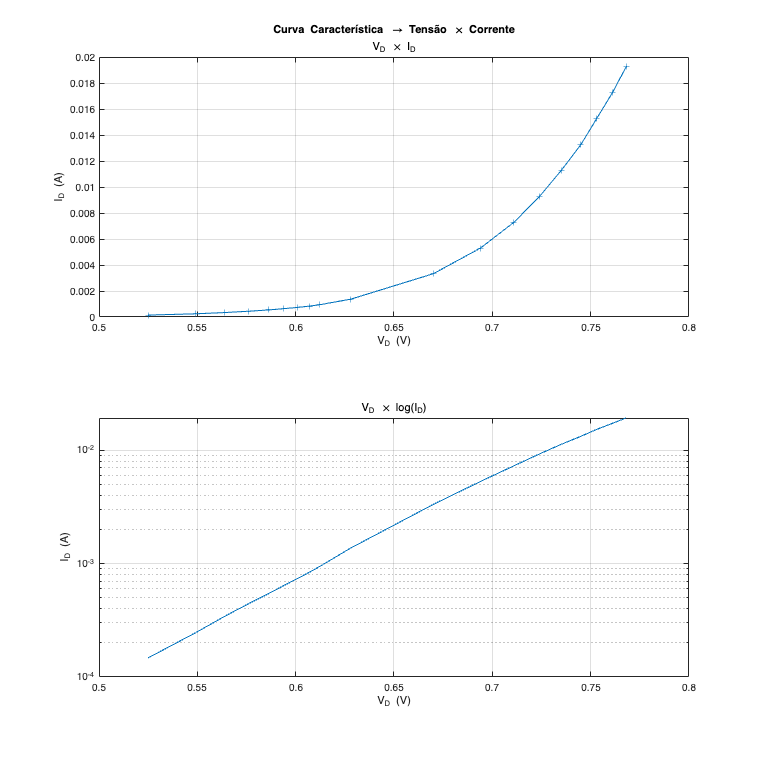

% Ler os dados do arquivo do google sheets em CSV
dados_experimentais = readtable("dados/curva_caracteristica/Experimento 2 - Página1.csv");
dados_experimentais.Vd = dados_experimentais.Vd * 10^-3;

% Calcular a corrente do diodo
corrente = @(vcc, vd, r) (vcc-vd)./r;
dados_experimentais.Corrente = corrente(dados_experimentais.Vin, dados_experimentais.Vd, dados_experimentais.R);

% Vamos tentar curve fitting os nossos dados para o modelo exponencial

% Agora vamos plotar Vd x Id
clf;
subplot(2, 1, 1);
plot(dados_experimentais.Vd, dados_experimentais.Corrente, 'Marker','+');
title("Curva Característica \rightarrow Tensão \times Corrente");
subtitle("V_{D} \times I_{D}");
xlabel("V_D (V)");
ylabel("I_D (A)");
grid on;

subplot(2, 1, 2);
semilogy(dados_experimentais.Vd, dados_experimentais.Corrente);
subtitle("V_{D} \times log(I_{D})");
ylabel("I_D (A)");
xlabel("V_D (V)");
grid on;

fprintf("Corrente Mínima: %d\n Corrente Máxima: %d", min(dados_experimentais.Corrente), max(dados_experimentais.Corrente));

Corrente Mínima: 1.475000e-04
 Corrente Máxima: 1.923200e-02

### 3.2 Retificadores

#### 3.2.1 Retificadores de Meia-Onda

Ao construírmos o circuito retificador de meia onda, com somente um diodo e um resistor, como mostrado abaixo, nós tivemos os seguintes resultados:

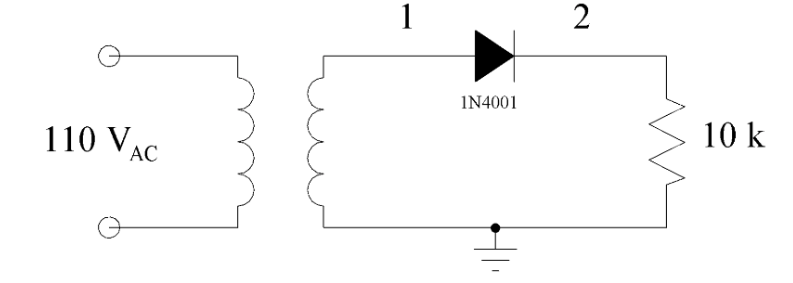

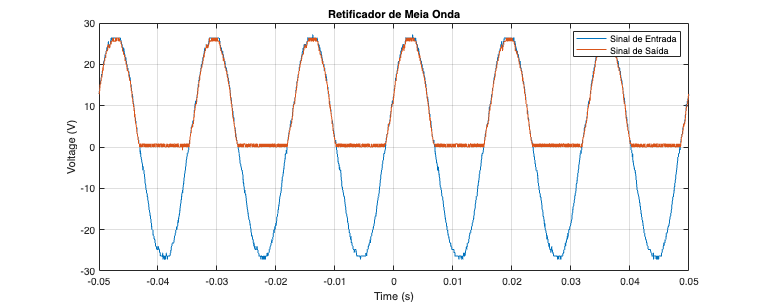

meia_onda_dados_ch1 = readtable("dados/retiricador_meia_onda/F0003CH1.CSV");
meia_onda_dados_ch2 = readtable("dados/retiricador_meia_onda/F0003CH2.CSV");

% Remove trash data and rename the columns
meia_onda_dados_ch1 = clear_osciloscope_data(meia_onda_dados_ch1);
meia_onda_dados_ch2 = clear_osciloscope_data(meia_onda_dados_ch2);

% Plot the reading
clf;
plot(meia_onda_dados_ch1.Time, meia_onda_dados_ch1.Reading, meia_onda_dados_ch2.Time, meia_onda_dados_ch2.Reading);
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Retificador de Meia Onda');
legend('Sinal de Entrada', 'Sinal de Saída');
fig=gcf;
fig.Position(3:4)=[1000,400];
grid on;

#### 3.2.2 Retificador de Onda-Completa Tipo Ponte

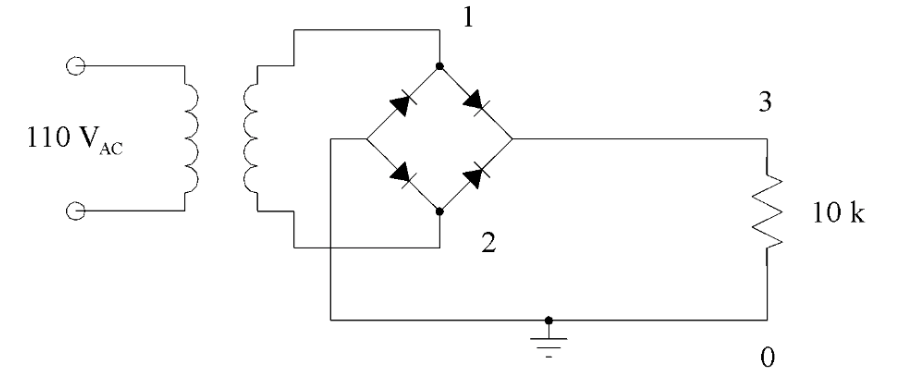

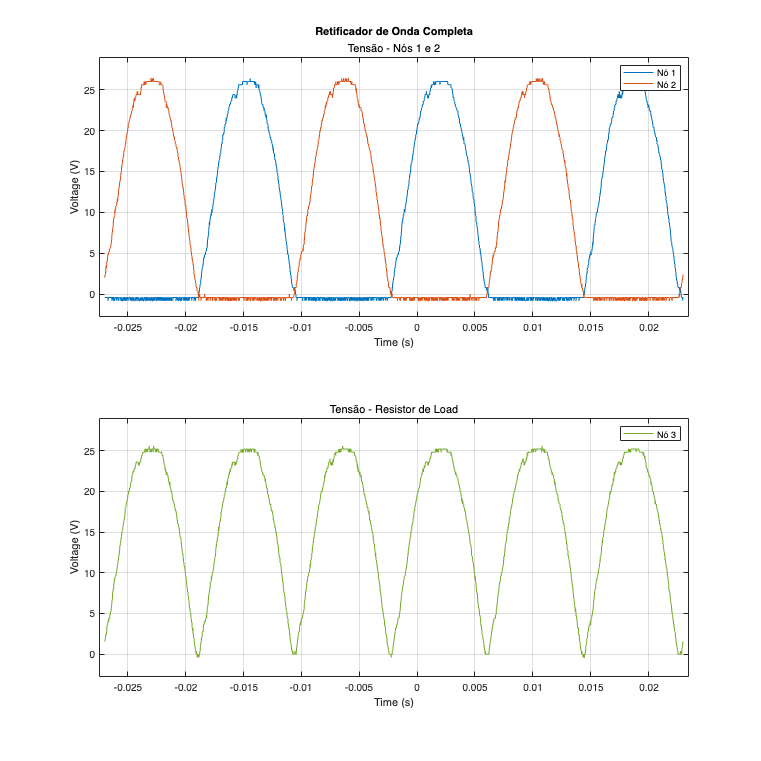

% Load the data files
onda_completa_dados_ch1 = readtable("dados/retiricador_onda_completa/1_reading/F0000CH1.CSV");
onda_completa_dados_ch2 = readtable("dados/retiricador_onda_completa/1_reading/F0000CH2.CSV");
onda_completa_dados_ch3 = readtable("dados/retiricador_onda_completa/2_reading/F0001CH2.CSV");

% Clean the data files 
onda_completa_dados_ch1 = clear_osciloscope_data(onda_completa_dados_ch1);
onda_completa_dados_ch2 = clear_osciloscope_data(onda_completa_dados_ch2);
onda_completa_dados_ch3 = clear_osciloscope_data(onda_completa_dados_ch3);

% Plot the readings
clf;
subplot(2, 1, 1);
plot(onda_completa_dados_ch1.Time, onda_completa_dados_ch1.Reading, onda_completa_dados_ch2.Time, onda_completa_dados_ch2.Reading);

title('Retificador de Onda Completa');
subtitle('Tensão - Nós 1 e 2');
legend('Nó 1', 'Nó 2');
xlabel('Time (s)');

ylabel('Voltage (V)');
xlim([-0.0275 0.0235]);
ylim([-2.8 29.0]);
grid on;

subplot(2, 1, 2);
plot(onda_completa_dados_ch3.Time, onda_completa_dados_ch3.Reading, "Color",[0.4660 0.6740 0.1880]	);

subtitle('Tensão - Resistor de Load');
legend('Nó 3');
xlabel('Time (s)');
ylabel('Voltage (V)');

xlim([-0.0275 0.0235]);
ylim([-2.8 29.0]);
fig = gcf;
fig.Position(3:4) = [1000 1000];
grid on;

nos_infos = table('Size', [3 4], 'VariableTypes', {'string', 'double', 'double', 'double'}, VariableNames={'Nó', 'V_min', 'V_max', 'V_med'});
nos_infos.("Nó") = ["Nó 1" "Nó 2" "Nó 3"]';
nos_infos.V_min = [min(onda_completa_dados_ch1.Reading) min(onda_completa_dados_ch2.Reading) min(onda_completa_dados_ch3.Reading)]';
nos_infos.V_max = [max(onda_completa_dados_ch1.Reading) max(onda_completa_dados_ch2.Reading) max(onda_completa_dados_ch3.Reading)]';
nos_infos.V_med = [mean(onda_completa_dados_ch1.Reading) mean(onda_completa_dados_ch2.Reading) mean(onda_completa_dados_ch3.Reading)]'

nos_infos = 3×4 table
      Nó      V_min    V_max    V_med 
    ______    _____    _____    ______

    "Nó 1"    -0.8     26.4     8.0816
    "Nó 2"    -0.8     26.4     8.1466
    "Nó 3"    -0.4     25.6     15.903


#### Inclusão do Capacitor 

Ao adicionarmos um capacitor em paralelo com a saída (que no nosso caso é o resistor de load) vemos que ocorre a "retificação" da onda de saída devido a carga do capacitor compensar os momentos de queda de tensão. Ao analizarmos atentamente, entretanto, podemos observar a presença do efeito ripple:

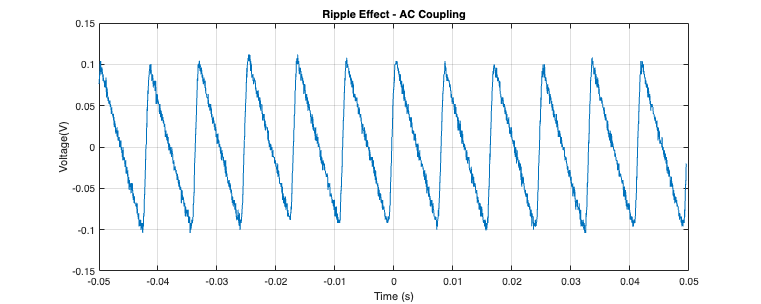

% Load the data and clean it
capacitor_data = readtable("dados/retiricador_onda_completa/3_reading/F0002CH2.CSV");
capacitor_data = clear_osciloscope_data(capacitor_data);

% Plot the data
clf;
plot(capacitor_data.Time, capacitor_data.Reading);
title('Ripple Effect - AC Coupling');
xlabel('Time (s)');
ylabel('Voltage(V)');
xlim([-0.05 0.05]);
fig = gcf;
fig.Position(3:4) = [1000 400];
grid on;